# Stability

#### Plotting stability regions

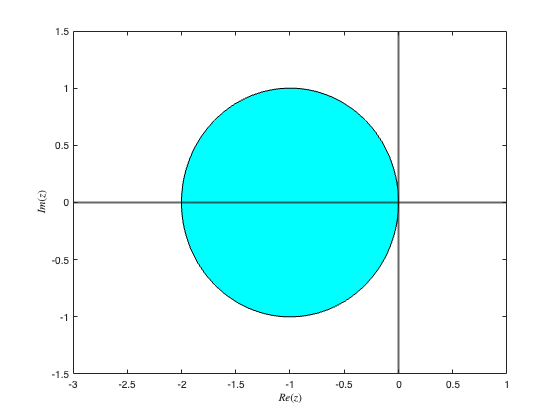

% Generate z values
xmin = -3;
xmax = 1;
ymin = -1.5;
ymax = 1.5;
[X, Y] = meshgrid(linspace(xmin, xmax, 200), linspace(ymin, ymax, 200));
Z = X + Y * 1i;

% Define stability function 
R = 1 + Z;

% Plot stability region
contourf(X, Y, abs(R), [0, 1])
xline(0, LineWidth=2)
yline(0, LineWidth=2)
colormap([0, 1, 1 ; 1, 1, 1])
xlabel("$Re(z)$", Interpreter="latex")
ylabel("$Im(z)$", Interpreter="latex")

#### Example 18

An explicit Runge-Kutta method is defined by the following Butcher tableau


$$\begin{array}{c|cccc}
0 &  &  &  & \\
1/2 & 1/2 &  &  & \\
3/4 & 0 & 3/4 &  & \\
1 & 2/9 & 1/3 & 4/9 & \\ 
\hline
& 7/24 & 1/4 & 1/3 & 1/8
\end{array}$$


(i) Determine the stability function for this Runge-Kutta method and hence find its order;

% Define ERK method
A = [0, 0, 0, 0 ;
     1/2, 0, 0, 0 ;
     0, 3/4, 0, 0 ;
     2/9, 1/3, 4/9, 0];
b = [7/24 ; 1/4 ; 1/3 ; 1/8];
e = ones(4, 1);

% Calculate coefficients 
for k = 1 : 5
    sym(b' * A ^ (k - 1) * e)
end

$$ans = 1$$

$$ans = \frac{1}{2}$$

$$ans = \frac{3}{16}$$

$$ans = \frac{1}{48}$$

$$ans = 0$$

Therefore the stability function is $R(z) = 1 + z + \frac{1}{2}z^2 + \frac{3}{16}z^3 + \frac{1}{48}z^4$ and it is a second-order method.

(ii) plot the region of absolute stability and that of an explicit method on the same order on the same set of axes;

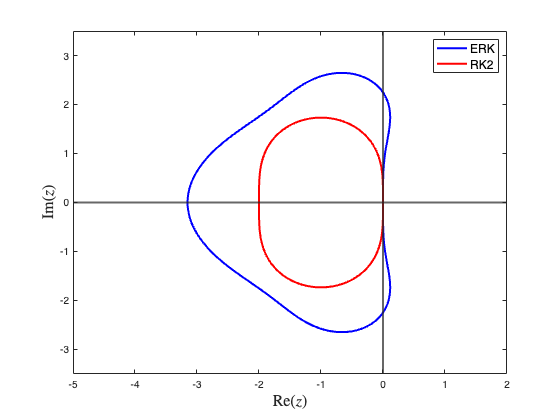

% Generate z values
xmin = -5;
xmax = 2;
ymin = -3.5;
ymax = 3.5;
[X, Y] = meshgrid(linspace(xmin, xmax, 200), linspace(ymin, ymax, 200));
Z = X + Y * 1i;

% Define stability function 
ERK = 1 + Z + 1/2 * Z .^ 2 + 3/16 * Z .^ 3 + 1/48 * Z .^ 4;
RK2 = 1 + Z + 1/2 * Z .^ 2;

% Plot the region of absolute stability
contour(X, Y, abs(ERK), [1, 1], 'b-', 'linewidth', 2)
hold on
contour(X, Y, abs(RK2), [1, 1], 'r-', 'linewidth', 2)
hold off
xline(0, LineWidth=2)
yline(0, LineWidth=2)
axis([xmin, xmax, ymin, ymax])
xlabel('$\mathrm{Re}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$\mathrm{Im}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
legend('ERK', 'RK2', FontSize=12)

(iii) comment on the region of absolute stability of the two methods.

The interval of absolute stability for this method is $[-3,0]$ whereas for the second-order method we have $[-2,0]$. This means that this method is stable for larger values of $h$ so we can use fewer steps than the second-order method to calculate the solution to the same accuracy, although it does require the calculation of two additional stage values.

#### Example 19

An implicit Runge-Kutta method is defined by the following Butcher tableau


$$\begin{array}{c|cc}
    0 & 1/4 & -1/4 \\
    2/3 & 1/4 & 5/12 \\ \hline
    & 1/4 & 3/4
    \end{array}$$


Determine whether this method is A-stable and plot the region of absolute stability.

% Define IRK method
A = [1/4, -1/4 ; 1/4, 5/12];
ebT = [1/4, 0 ; 0, 3/4];

% Calculate R(z)
P = @(z) det(eye(2) - z * A + z * ebT);
Q = @(z) det(eye(2) - z * A);

syms z
Rz = P(z) / Q(z)

$$Rz = \frac{\frac{z^{2}}{16}+\frac{z}{3}+1}{\frac{z^{2}}{6}-\frac{2\,z}{3}+1}$$

P = @(z) 1 + 1/3 * z + 1/16 * z ^ 2;
Q = @(z) 1 - 2/3 * z + 1/6 * z ^ 2;

% Check roots of Q(z)
solve(Q(z))

$$ans = \left(\begin{array}{c} 2-\sqrt{2}\,\mathrm{i}\\ 2+\sqrt{2}\,\mathrm{i} \end{array}\right)$$

% Check E(y) >= 0
syms y
simplify(Q(1i * y) * Q(-1i * y) - P(1i * y) * P(-1i * y))

$$ans = \frac{y^{2}\,\left(55\,y^{2}+288\right)}{2304}$$

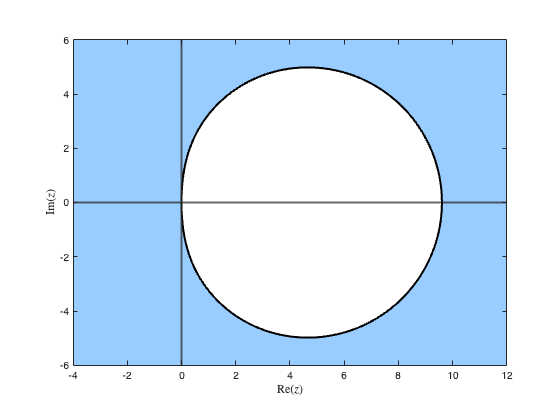

% Generate z values
xmin = -4;
xmax = 12;
ymin = -6;
ymax = 6;
[X, Y] = meshgrid(linspace(xmin, xmax, 200), linspace(ymin, ymax, 200));
Z = X + Y * 1i;

% Define stability function 
R = (1 + 1/3 * Z + 1/16 * Z .^ 2) ./ (1 - 2/3 * Z + 1/6 * Z .^ 2);

% Plot stability region
contourf(X, Y, abs(R), [0, 1], LineWidth=2)
xline(0, LineWidth=2)
yline(0, LineWidth=2)
colormap([153, 204, 255 ; 255, 255, 255] / 255)
axis equal
axis([xmin, xmax, ymin, ymax])
xlabel("$\mathrm{Re}(z)$", FontSize=12, Interpreter="latex")
ylabel("$\mathrm{Im}(z)$", FontSize=12, Interpreter="latex")

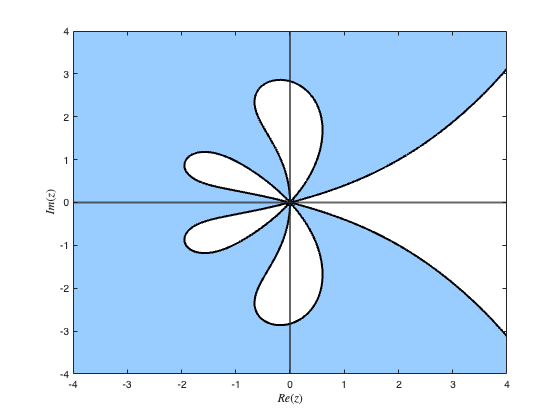

% Generate z values
xmin = -4;
xmax = 4;
ymin = -4;
ymax = 4;
[X, Y] = meshgrid(linspace(xmin, xmax, 200), linspace(ymin, ymax, 200));
Z = X + Y * 1i;

% Define stability function 
R = 1 + Z + 1/2 * Z .^ 2 + 1/6 * Z .^ 3 + 1/24 * Z .^ 4;

% Plot order star
contourf(X, Y, abs(R ./ exp(Z)), [0, 1], LineWidth=2)
xline(0, LineWidth=2)
yline(0, LineWidth=2)
colormap([255, 255, 255 ; 153, 204, 255] / 255)
axis([xmin, xmax, ymin, ymax])
xlabel("$Re(z)$", FontSize=12, Interpreter="latex")
ylabel("$Im(z)$", FontSize=12, Interpreter="latex")

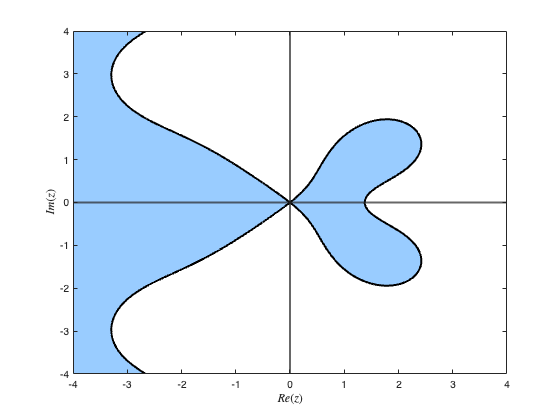

% Generate z values
xmin = -4;
xmax = 4;
ymin = -4;
ymax = 4;
[X, Y] = meshgrid(linspace(xmin, xmax, 200), linspace(ymin, ymax, 200));
Z = X + Y * 1i;

% Define stability function 
R = (1 + 1/3 * Z + 1/16 * Z .^ 2) ./ (1 - 2/3 * Z + 1/6 * Z .^ 2);

% Plot order star
contourf(X, Y, abs(R ./ exp(Z)), [0, 1], LineWidth=2)
xline(0, LineWidth=2)
yline(0, LineWidth=2)
colormap([255, 255, 255 ; 153, 204, 255] / 255)
axis([xmin, xmax, ymin, ymax])
xlabel("$Re(z)$", FontSize=12, Interpreter="latex")
ylabel("$Im(z)$", FontSize=12, Interpreter="latex")